# Matched Filtering with Neural Networks

## Intro

It is well known that nonlinear noise can hinder the ability of a matched filter to recover its signal.  This analysis intends to demonstrate that impairment and demonstrate the ability of a neural network to recover a signal corrupted by nonlinear noise.

## Setup

% Set default interpreter to latex for plotting
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
set(groot, 'defaultTextInterpreter','latex');

clc; clear; close all;

rng(1);


## Signal

Here we instantiate an examplary sinusoidal pulse:


$$s\left(t\right)=a\left(\theta \text{\,}\left(t-t_{start} \right)-\theta \text{\,}\left(t-t_{end} \right)\right)sin\left(2\pi \omega t\right)$$


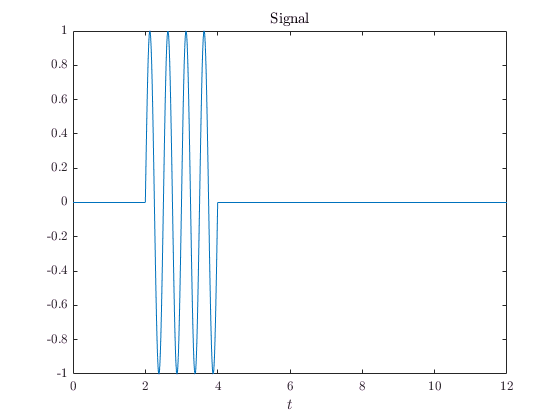

% Signal
omega = 2;
a = 1;
start = 2;
stop = 4;

% Time
dt = 0.001;
t_end = 2*(start + stop);
t = 0:dt:t_end;

signal = a*(heaviside(t - start) - heaviside(t - stop)).*sin(2*pi*omega*t);

figure;
plot(t, signal);
title('Signal');
xlabel('$$t$$');

## Matched Filter

A matched filter for the signal above is given as a time revsered version of the original signal:


$$h\left(t\right)=\theta \text{\,}\left(t-\left(t_{stop} -t_{end} \right)\right)sin\left(-2\pi \omega t\right)$$


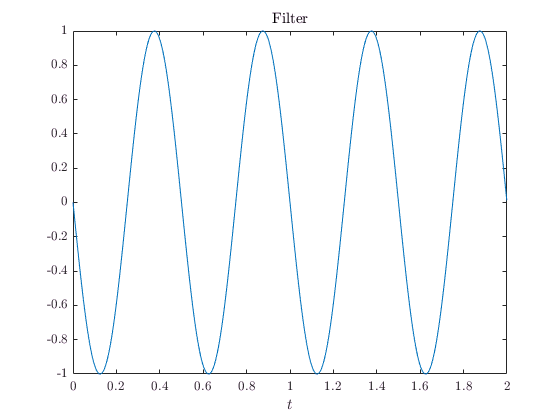

% Matched filter
filter_time = t(t < stop - start);
h = sin(-2*pi*omega*filter_time);

figure;
plot(filter_time, h);
title('Filter');
xlabel('$$t$$');

## Gaussian Noise

In standard signal processing design, signals are often assumed to be corrupted by additive white gaussian noise.  Exemplary gaussian noise $\eta_G \left(t\right)$ is instantiated with the PDF:


$$f_G =\frac{1}{\sigma \sqrt{2\pi }}exp\left(\frac{1}{2}{\left(\frac{x-\mu \text{\,}}{\sigma \text{\,}}\right)}^2 \right)$$


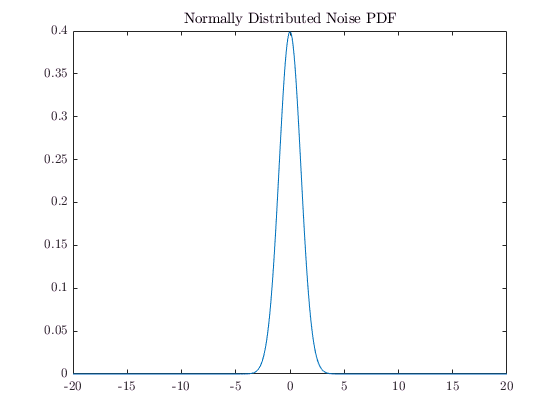


% Noise params
x0 = -20;
x1 = 20;
dx = 0.01;
x = x0:dx:x1;
num_samples = length(t);

% Noise generator (normal)
sigma = 1;
mu = 0;
normal_pdf_handle = @(x) 1/(sigma*sqrt(2*pi))*exp(-0.5*((x-mu)/sigma).^2);

normal_noise = GenerateDistributedData( ...
        x0, x1, dx, normal_pdf_handle, num_samples);

normal_noise_corrupted_signal = signal + normal_noise;

figure;
plot(x, normal_pdf_handle(x));
title('Normally Distributed Noise PDF');

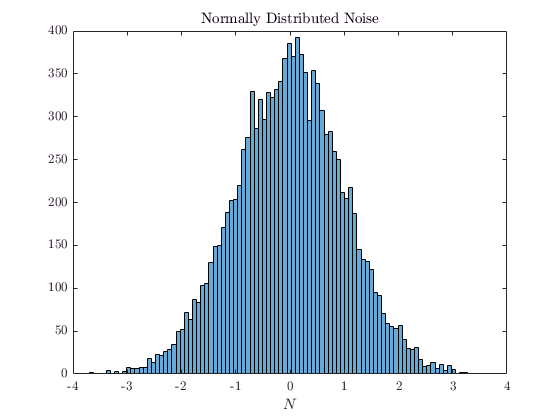


figure;
histogram(normal_noise, 100);
title('Normally Distributed Noise');
xlabel('$$N$$');

## Signal Corrupted by Gaussian Noise

A signal corrupted by white Gaussian noise is given by:


$$\hat{s_G } \left(t\right)=s\left(t\right)+\eta_G \left(t\right)$$


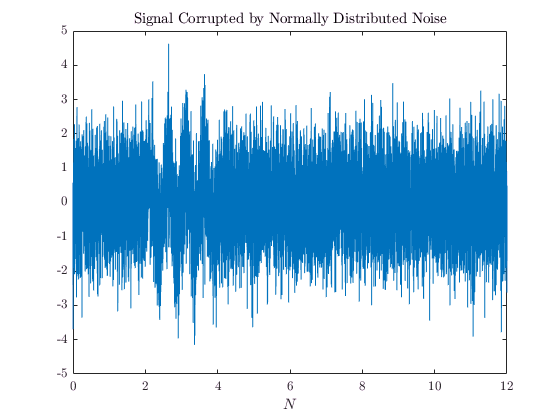

figure;
plot(t, normal_noise_corrupted_signal);
title('Signal Corrupted by Normally Distributed Noise');
xlabel('$$N$$');

## Nonlinear Noise

When a channel is modeled in high fidelity or measured, it is often observed that nonlinearities are present which hinder the recovery of signals via linear matched filtering.

We model nonlinear noise here as a polynomial function of the original signal wherein each term of the polynomial has a given statistical distribution:


$$\Sigma \eta_N \left(t\right)=\sum_{n=0}^{N} a_n {\text{\,}\eta }_n \left(t\right)s^n \left(t\right)$$


Here each $\eta_n \left(t\right)$ represents time domain noise having PDF $f_n \left(x\right)$ which need not be gaussian.

In an application of the techniques presented, this model and its distributions would be derived via physics.  Here however, we simply present an illustrative nonlinear model.

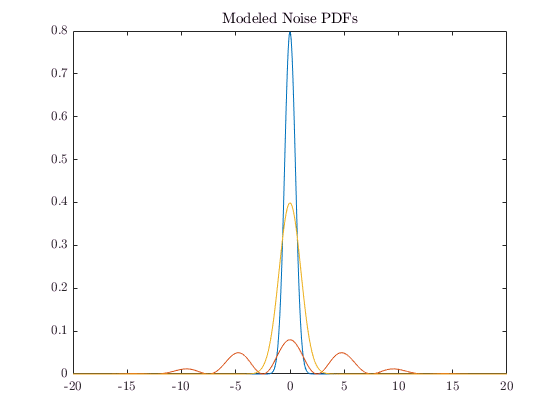

% Noise generator (nonlinear)
mu = [0 0 0];
sigma = [0.5 5 1];

modeled_pdf_handle0 = ...
    @(x) 1/(sigma(1)*sqrt(2*pi))*exp(-0.5*((x - mu(1))/sigma(1)).^2);
modeled_pdf_handle1 = ...
    @(x) 1/(sigma(2)*sqrt(2*pi))*exp(-0.5*((x - mu(2))/sigma(2)).^2).*cos(2*pi*0.1*x).^2;
modeled_pdf_handle2 = ...
    @(x) 1/(sigma(3)*sqrt(2*pi))*exp(-0.5*((x - mu(3))/sigma(3)).^2);

modeled_noise0 = GenerateDistributedData( ...
        x0, x1, dx, modeled_pdf_handle0, num_samples);
    
modeled_noise1 = GenerateDistributedData( ...
        x0, x1, dx, modeled_pdf_handle1, num_samples);
    
modeled_noise2 = GenerateDistributedData( ...
        x0, x1, dx, modeled_pdf_handle2, num_samples);
    
a0 = 4;
a1 = 2;
a2 = 1;

modeled_noise_corrupted_signal = ...
    a0*modeled_noise0 + a1*modeled_noise1.*signal + a2*modeled_noise2.*signal.^2;

figure;
plot(x, modeled_pdf_handle0(x));
hold on;
plot(x, modeled_pdf_handle1(x));
plot(x, modeled_pdf_handle2(x));
title('Modeled Noise PDFs');

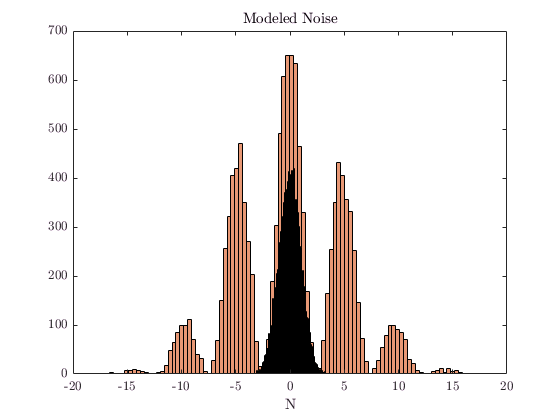


figure;
histogram(modeled_noise0, 100);
hold on;
histogram(modeled_noise1, 100);
histogram(modeled_noise2, 100);
title('Modeled Noise');
xlabel('N');

## Signal Corrupted by Modeled Noise

A signal corrupted by modeled noise then is given:


$$\hat{s_N } \left(t\right)=\sum_{n=0}^{N} a_n {\text{\,}\eta }_n \left(t\right)s^n \left(t\right)$$


Note that visually, the signal is easy to identify, and obviously present amonst the noise.

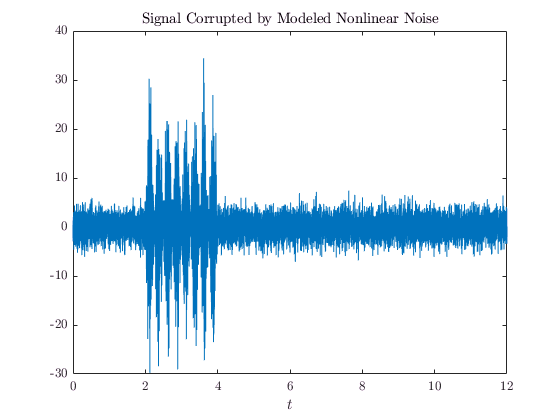

figure;
plot(t, modeled_noise_corrupted_signal);
title('Signal Corrupted by Modeled Nonlinear Noise');
xlabel('$$t$$');

## Matched Filter Recovery and Detection

A traditional matched filter is instantiated:


$$y\left(t\right)=\left(s\ast h\right)\left(t\right)$$



$$y\left(t\right)=\int_0^t \hat{s} \left(\tau \right)h\left(t-\tau \text{\,}\right)d\tau \text{\,}$$


For each of our signals, the filter output is given:


$$y_G \left(t\right)=$$

$$\int_0^t \left(a\left(\theta \text{\,}\left(\tau \text{\,}-t_{\text{start}} \right)-\theta \text{\,}\left(\tau \text{\,}-t_{\text{end}} \right)\right)\sin \left(2\pi \omega \tau \text{\,}\right)+\eta_G \left(t\right)\right)\theta \text{\,}\left(t-\left(t_{\text{stop}} -t_{\text{end}} \right)\right)\sin \left(-2\pi \omega \left(t-\tau \text{\,}\right)\right)d\tau \text{\,}$$



$$y_N \left(t\right)=$$

$$\int_0^t \sum_{n=0}^{N} a_n {\text{\,}\eta }_n \left(t\right)s^n \left(t\right)\theta \text{\,}\left(t\right)\theta \text{\,}\left(t-\left(t_{\text{stop}} -t_{\text{end}} \right)\right)\sin \left(-2\pi \omega \left(t-\tau \text{\,}\right)\right)d\tau \text{\,}$$



$$=\sum_{n=0}^{N} \int_0^t a_n {\text{\,}\eta }_n \left(t\right)s^n \left(t\right)\theta \text{\,}\left(t\right)\theta \text{\,}\left(t-\left(t_{\text{stop}} -t_{\text{end}} \right)\right)\sin \left(-2\pi \omega \left(t-\tau \text{\,}\right)\right)d\tau \text{\,}$$


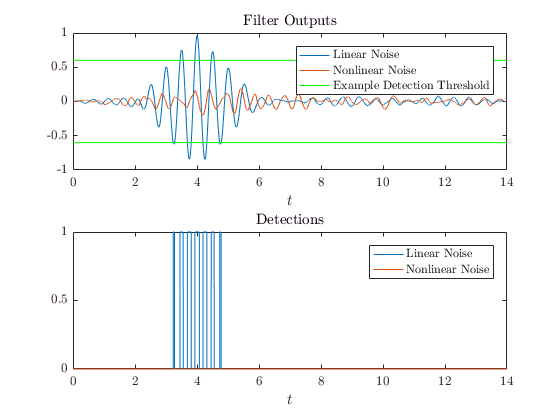

filtered_signal_normal_noise = conv(normal_noise_corrupted_signal, h)*dt;
filtered_signal_modeled_noise = conv(modeled_noise_corrupted_signal, h)*dt;

conv_n_samples = length(normal_noise_corrupted_signal) + length(h) - 1;
conv_time = 0:dt:conv_n_samples*dt - dt;

d = 0.6;
detection_threshold = d*ones(size(conv_time));
detections_normal = abs(filtered_signal_normal_noise) > detection_threshold;
detections_modeled = abs(filtered_signal_modeled_noise) > detection_threshold;

figure;
subplot(211);
plot(conv_time, filtered_signal_normal_noise);
hold on;
plot(conv_time, filtered_signal_modeled_noise);
plot(conv_time, detection_threshold, 'g');
plot(conv_time, -detection_threshold, 'g');
title('Filter Outputs')
legend('Linear Noise', 'Nonlinear Noise', 'Example Detection Threshold');
xlabel('$$t$$');
subplot(212);
plot(conv_time, detections_normal);
hold on;
plot(conv_time, detections_modeled);
title('Detections')
legend('Linear Noise', 'Nonlinear Noise');
xlabel('$$t$$');

Note that as expected the mached filter performs poorly for nonliner noise even though the signal is obviously present.

## Neural Net Matched Filtering

Here we train a neural network to learn the output map:


$$y\left(t\right)=f\left(x\left(t\right)\right)$$


Where the input of the neural net is given as the *nonlinearly* corrupted signal:


$$x\left(t\right)=\hat{s} \left(t\right)=\sum_{n=0}^{N} a_n {\text{\,}\eta }_n \left(t\right)s^n \left(t\right)$$


The output is given as the ideal detections (1 when pulse is present, 0 otherwise):


$$y\left(t\right)=\theta \text{\,}\left(\tau \text{\,}-t_{\text{start}} \right)-\theta \text{\,}\left(\tau \text{\,}-t_{\text{end}} \right)\text{\,}$$


Here we will train a neural net to show that this function is learnable.

We leave the following two questions to be explored in future work:

- Can a proof be constructed using the math from Sinusoidal Excitation of a Single Neuron (PRISM-AI, Sanchirico) of the learnability of this map?

- Will these results generalize to large training sets?

The first question is a research question which could be answered mathemtatically.  The second question could be easily answered experimentally through the existence of a physics based synthetic data generation tool.

% Noise model params:
a0 = 4;
a1 = 2;
a2 = 1;

n_signals = 2;
n_history = 20;
delay_per_copy = 1;

target_signal = 2*(heaviside(t - start) - heaviside(t - stop)) - 1;

x_training_signals = [];
t_target_signals = [];

fprintf('Generating training set (i.e. running AiMLogic synth data gen plugin)...\n');

Generating training set (i.e. running AiMLogic synth data gen plugin)...



% Create training set of signals
for idx = 1:n_signals
    modeled_noise0 = GenerateDistributedData( ...
        x0, x1, dx, modeled_pdf_handle0, num_samples);
    
    modeled_noise1 = GenerateDistributedData( ...
        x0, x1, dx, modeled_pdf_handle1, num_samples);
    
    modeled_noise2 = GenerateDistributedData( ...
        x0, x1, dx, modeled_pdf_handle2, num_samples);

    corrupted_signal = ...
        a0*modeled_noise0 ...
      + a1*modeled_noise1.*signal + a2*modeled_noise2.*signal.^2;
  
    % Copy the corrupted signals and delay each copy
    corrupted_signal_copies = GenerateDelayedCopies( ...
        corrupted_signal, n_history, delay_per_copy);
    
    % Cut the end of the convolution off since it only contains null values
    target_signal_cut = target_signal(conv_time < t_end + dt);
    
    x_training_signals = [x_training_signals corrupted_signal_copies];
    t_target_signals = [t_target_signals target_signal_cut];

end

size(x_training_signals)

ans =           20       24002


size(t_target_signals)

ans =            1       24002


fprintf('Training net...\n');

Training net...


net = feedforwardnet(n_history);
% Use first 10000 samples for training
% Next samples are new noise from a new run of the random number generator
net = train(net, x_training_signals(:, 1:10000), t_target_signals(:, 1:10000));

## Neural Net Matched Filter Testing

Here we pass the neural net a never before seen pulse with newly generated noise as a simple test that the learned weights generalize.

The output of the neural net is compared to the legacy matched filter.

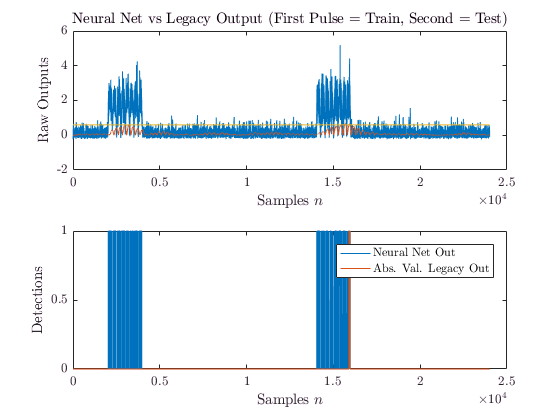

y_neural_net = net(x_training_signals);
y_matched_filter = conv(x_training_signals(1,:), h)*dt;

% Remove the tail of the convolution
y_matched_filter_cut = y_matched_filter(1:length(y_neural_net));
detection_threshold = d*ones(size(y_neural_net));
detections_neural_net = y_neural_net > detection_threshold;
detections_filter = y_matched_filter_cut > detection_threshold;

figure;
subplot(211)
plot(y_neural_net + 1);
hold on;
plot(abs(y_matched_filter_cut));
plot(detection_threshold);
xlabel('Samples $$n$$');
ylabel('Raw Outputs');
title('Neural Net vs Legacy Output (First Pulse = Train, Second = Test)');

subplot(212)
plot(detections_neural_net);
hold on;
plot(detections_filter);
legend( ...
    'Neural Net Out', ...
    'Abs. Val. Legacy Out', 'Detect. Threshold');
xlabel('Samples $$n$$');
ylabel('Detections');